# Materials classification - A1

clc; clear all; close all;

## Import dataset

image_data_folder = "Data\image\";
mask_data_folder = "Data\mask\";
image = Images_import(image_data_folder);
mask = Images_import(mask_data_folder);

% Each row of each matrix contains the paths of the images of an specific material, being
% the order of the rows: fabric, foliage, glass, leather, metal, paper,
% plastic, tone, water and wood
% Now, to have acces to an image we only have to do:
% imread(image(i,j)) or imread(mask(i,j))

## Create targets

for idx = 1:length(image)
    if contains(image(idx).path, "fabric")
        image(idx).target = "fabric";
        mask(idx).target = "fabric";
    elseif contains(image(idx).path, "foliage")
        image(idx).target = "foliage";
        mask(idx).target = "foliage";
    elseif contains(image(idx).path, "glass")
        image(idx).target = "glass";
        mask(idx).target = "glass";
    elseif contains(image(idx).path, "leather")
        image(idx).target = "leather";
        mask(idx).target = "leather";
    elseif contains(image(idx).path, "metal")
        image(idx).target = "metal";
        mask(idx).target = "metal";
    elseif contains(image(idx).path, "paper")
        image(idx).target = "paper";
        mask(idx).target = "paper";
    elseif contains(image(idx).path, "plastic")
        image(idx).target = "plastic";
        mask(idx).target = "plastic";
    elseif contains(image(idx).path, "stone")
        image(idx).target = "stone";
        mask(idx).target = "stone";
    elseif contains(image(idx).path, "water")
        image(idx).target = "water";
        mask(idx).target = "water";
    elseif contains(image(idx).path, "wood")
        image(idx).target = "wood";
        mask(idx).target = "wood";
    end
end

### Create test image set

% Apply the mask and save only the foreground object
imgData = [];
for idx = 1:length(image)
    tempImg = im2gray(imread(image(idx).path));
    tempMask = im2gray(imread(mask(idx).path));
    tempImg(~tempMask) = 0;
    imgData{idx} = tempImg;
end

inputs = ["fabric", "foliage", "glass", "leather", "metal", "paper", "plastic", "stone", "water", "wood"];

## Feature Extraction

### Feature 1: Entropy measure

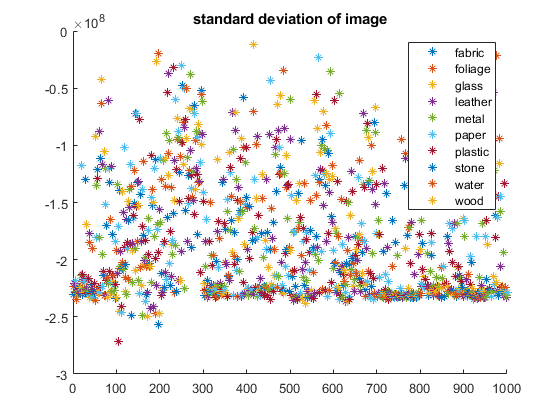

entropyVals = [];
for idx = 1:length(imgData)
    entropyVals(idx) = entropy(double(imgData{idx}(:)));
end
figure; hold on;
for idx = 1:length(imgData)
    plot(idx, entropyVals(idx), '*');
end
title("standard deviation of image")
hold off;
legend(inputs);

### Feature 2: Number of edges

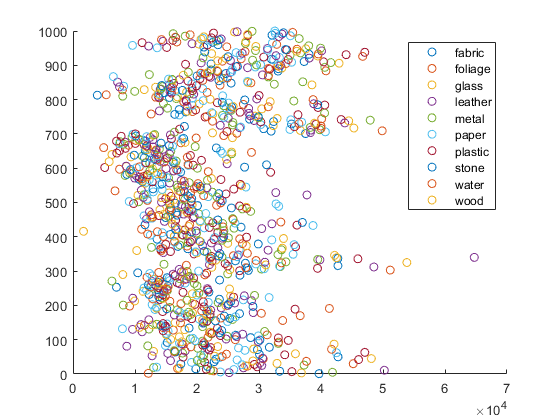

edgeCount = [];
for idx = 1:length(imgData)
    bw = edge(imgData{idx},'canny');
    edgeCount(idx) = nnz(bw);
end

figure; hold on;
for idx = 1:length(imgData)
    plot(edgeCount(idx), idx, 'o');
end
hold off;
legend(inputs);

### Feature 3: Std. deviation of image

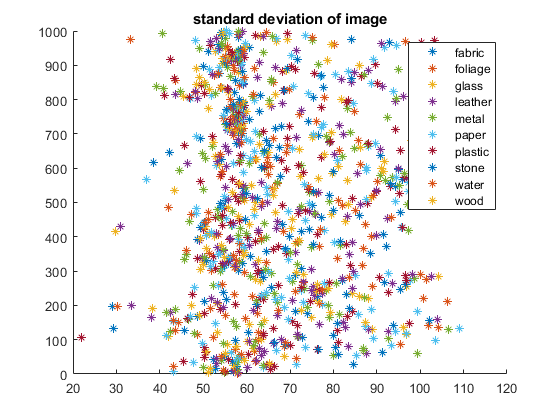

imgDev = [];
for idx = 1:length(imgData)
    imgDev(idx) = std(double(imgData{idx}(:)));
end
figure; hold on;
for idx = 1:length(imgData)
    plot(imgDev(idx), idx, '*');
end
title("standard deviation of image")
hold off;
legend(inputs);

save entropyVals.mat entropyVals
save edgeCount.mat edgeCount
save imgDev.mat imgDev

## Discretization and Training BN

load entropyVals.mat
load edgeCount.mat
load imgDev.mat


